**Dynamics control **

$M(q)\ddot{q} + C(q, \dot{q}) + N(q) = u$,

then to choose the following control law

$u  = M(q)[M(q)^{-1}(C(q,\dot{q}) + N(q)) + u']$,

and to come up with the following torque equation 

$\tau = M(q)u' + C(q, \dot{q}) + N(q)$,

where $u' $ is the additional control effort 

$u' = \ddot{q}_d + K_v(\dot{q}_d -\dot{q}_a)+ K_p (q_d-q_a)$,

where $\ddot{q}_d$ is the desired acceleration, $\dot{q}_d, \dot{q}_a$ are the desired and actual angular velocities, $q_d, q_a$ are the desired and actual positions, $K_v,  K_p $ are coefficients

clear; clc;
% to clear the workspace and command window 
format short;

Variables 

$q_1, \; q_2, \; q_3  $ are the angles of rotations, $dq_1, \; dq_2, \; dq_3  $ are the angular velocities,  $f_x, \; f_y, \; f_z$ are external load

$l_1,\; l_2, \; l_3$ are lengths, $m_1, \;  m_2, \; m_3 $ are masses, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}, j_{x_3}, j_{y_3}, j_{z_3} $ are inertias, and $g$ is gravity constant

syms q1 q2 q3 dq1 dq2 dq3 fx fy fz
syms l1 l2 l3 m1 m2 m3 jx1 jy1 jz1 jx2 jy2 jz2 jx3 jy3 jz3 g 

addpath(genpath('mr')); % we use function library by Kevin Lynch 

Generalized coordinates are the angles of rotations, dq stands for the angular velocities 

q = [q1, q2, q3]; 
dq = [dq1, dq2, dq3];

Vectors of unit angular velocities 

w1=[0;0;0]

w1 =      0
     0
     0


w2=[0;0;0]

w2 =      0
     0
     0


w3=[0;0;1] % there is no rotation for the prismatic joint

w3 =      0
     0
     1


Positon of joints 

r1=[0;0;q1]

$$r1 = \left(\begin{array}{c} 0\\ 0\\ q_{1} \end{array}\right)$$

r2=[0;0;q1+q2]

$$r2 = \left(\begin{array}{c} 0\\ 0\\ q_{1}+q_{2} \end{array}\right)$$

r3=[0;0;q1+q2+q3]

$$r3 = \left(\begin{array}{c} 0\\ 0\\ q_{1}+q_{2}+q_{3} \end{array}\right)$$

Vectors of translation motion

v1_unit=[0;0;1]; 
% VecToso3 is a function from mr for skew-symmetric representation
v2_unit=[0;0;1];
v3_unit=-VecToso3(w3)*r3 % prismatic joint along y axis

$$v3\_unit = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Unit twists or screws the links 

S1=[w1;v1_unit];
S2=[w2;v2_unit];
S3=[w3;v3_unit];

Home position of CoM and ee 

Here by Hc10 I have denoted $H_{c_1}^{0}$. 

Hc10_home=[eye(3,3), [0;0;l1/2];  0,0,0,1]

$$Hc10\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc20_home=[eye(3,3), [0;0;(l1+l2)/2];  0,0,0,1]

$$Hc20\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}+\frac{l_{2}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc30_home=[eye(3,3), [0;0;(l1+l2+l3)/2];  0,0,0,1]

$$Hc30\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}+\frac{l_{2}}{2}+\frac{l_{3}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hee0_home=[eye(3,3), [0;0;(l1+l2+l3)/2];  0,0,0,1]

$$Hee0\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}+\frac{l_{2}}{2}+\frac{l_{3}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotation matrixes 


$$R=e^{\tilde{w}}=I+\tilde{w}\sin{\theta}+\tilde{w}^2(1-\cos{\theta})$$


In code by Rij I have denoted $R_i^j$ 

R10=eye(3,3)+VecToso3(w1)*sin(q1)+VecToso3(w1)^2*(1-cos(q1)) % matrix exponential rodrigues formula

$$R10 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

R21=eye(3,3)+VecToso3(w2)*sin(q2)+VecToso3(w2)^2*(1-cos(q2)); 
R32=eye(3,3)+VecToso3(w3)*sin(q3)+VecToso3(w3)^2*(1-cos(q3)); 

#### Homogeneous transformation matrixes 

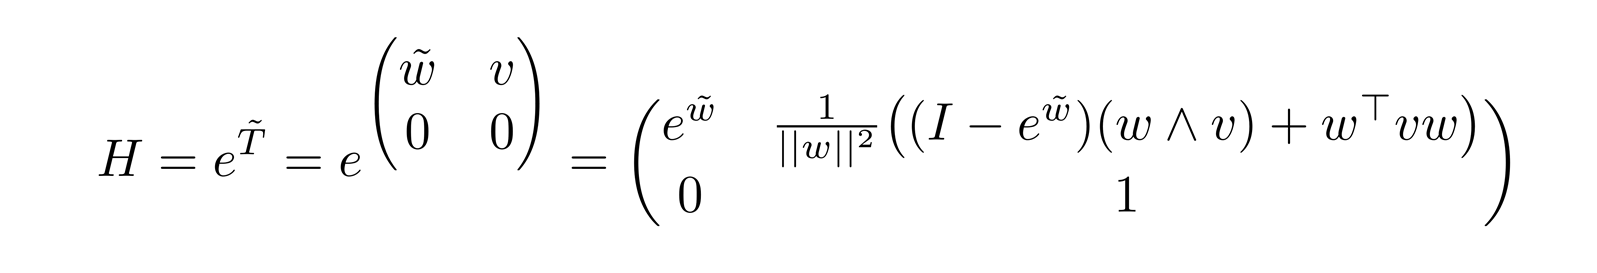

abs_ter_1=(eye(3,3)*q1+(1-cos(q1))*VecToso3(w1)+(q1-sin(q1))*VecToso3(w1)^2)*v1_unit;
abs_ter_2=(eye(3,3)*q2+(1-cos(q2))*VecToso3(w2)+(q2-sin(q2))*VecToso3(w2)^2)*v2_unit;
abs_ter_3=(eye(3,3)*q3+(1-cos(q3))*VecToso3(w3)+(q3-sin(q3))*VecToso3(w3)^2)*v3_unit;

Here by T100 I have denoted $T_1^{0,0}$

e_T100q1=[R10, abs_ter_1; 0,0,0,1];
e_T201q2=[R21, abs_ter_2; 0,0,0,1];
e_T302q3=[R32, abs_ter_3; 0,0,0,1]

$$e\_T302q3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Direct kinematics 


$$H_n^0 (q_1, q_2, \dots q_n)=
e^{\tilde{\hat{T}}_1^{0,0}q_1} e^{\tilde{\hat{T}}_2^{0,1}q_2} \dots
e^{\tilde{\hat{T}}_n^{0,(n-1)}q_n} H_n^{0}(0),
$$


Hc10=simplify(e_T100q1*Hc10_home);
Hc20=simplify(e_T100q1*e_T201q2*Hc20_home);
Hc30=simplify(e_T100q1*e_T201q2*e_T302q3*Hc30_home);
Hee0=simplify(e_T100q1*e_T201q2*e_T302q3*Hee0_home);
P=Hee0*[0;0;0;1];

Hc01=TransInv(Hc10);
Hc02=TransInv(Hc20);
Hc03=TransInv(Hc30);
H0ee=TransInv(Hee0)

$$H0ee = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & \sin\left(q_{3}\right) & 0 & 0\\ -\sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & -\frac{l_{1}}{2}-\frac{l_{2}}{2}-\frac{l_{3}}{2}-q_{1}-q_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TransInv is a function from mr to take an inverse of H / TransInv 

#### Geometriacal Jacobians 

J1=S1;
J2=simplify(Adjoint(e_T100q1*e_T201q2)*S2);
J3=simplify(Adjoint(e_T100q1*e_T201q2*e_T302q3)*S3);
J_1=[J1, zeros(6,1), zeros(6,1)];
J_2=[J1, J2, zeros(6,1)];
J_3=[J1, J2, J3]

$$J\_3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 1\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 0 \end{array}\right)$$

Coordinates of CoM

zc1=[0, 0, 1, 0]*Hc10*[0;0;0;1];
zc2=[0, 0, 1, 0]*Hc20*[0;0;0;1];
zc3=[0, 0, 1, 0]*Hc30*[0;0;0;1]

$$zc3 = \frac{l_{1}}{2}+\frac{l_{2}}{2}+\frac{l_{3}}{2}+q_{1}+q_{2}$$

Inertia

j1=[jx1, 0, 0; 0, jy1, 0; 0, 0, jz1];
j2=[jx2, 0, 0; 0, jy2, 0; 0, 0, jz2];
j3=[jx3, 0, 0; 0, jy3, 0; 0, 0, jz3];
I1=[j1, zeros(3,3); zeros(3,3), eye(3,3)*m1];
I2=[j2, zeros(3,3); zeros(3,3), eye(3,3)*m2];
I3=[j3, zeros(3,3); zeros(3,3), eye(3,3)*m3]

$$I3 = \left(\begin{array}{cccccc} {\mathrm{jx}}_{3} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{jy}}_{3} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{jz}}_{3} & 0 & 0 & 0\\ 0 & 0 & 0 & m_{3} & 0 & 0\\ 0 & 0 & 0 & 0 & m_{3} & 0\\ 0 & 0 & 0 & 0 & 0 & m_{3} \end{array}\right)$$

#### Mass matrix and other terms of dynamic equation 

M_1 = simplify(J_1.'*Adjoint(Hc01).'*I1*Adjoint(Hc01)*J_1);
M_2 = simplify(J_2.'*Adjoint(Hc02).'*I2*Adjoint(Hc02)*J_2);
M_3 = simplify(J_3.'*Adjoint(Hc03).'*I3*Adjoint(Hc03)*J_3);
M = M_1+M_2+M_3

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & m_{2}+m_{3} & 0\\ m_{2}+m_{3} & m_{2}+m_{3} & 0\\ 0 & 0 & {\mathrm{jz}}_{3} \end{array}\right)$$


V = simplify(m1*g*zc1+m2*g*zc2+m3*g*zc3);
N = simplify([diff(V,q1); diff(V,q2); diff(V,q3)])

$$N = \left(\begin{array}{c} g\,\left(m_{1}+m_{2}+m_{3}\right)\\ g\,\left(m_{2}+m_{3}\right)\\ 0 \end{array}\right)$$

C = simplify(getC(M, q ,dq))

$$C = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Wrench 

W = [0, 0, 0, fx, fy, fz]

$$W = \left(\begin{array}{cccccc} 0 & 0 & 0 & \mathrm{fx} & \mathrm{fy} & \mathrm{fz} \end{array}\right)$$

Joints' torque 

tau = simplify(J_3.'*Adjoint(H0ee).'*W.')

$$tau = \left(\begin{array}{c} \mathrm{fz}\\ \mathrm{fz}\\ 0 \end{array}\right)$$

function [C] = getC(M, q, dq)

    n = size(M, 1);
    G = sym(zeros(n, n, n)); % cristofil symbol G_ijk
   
    for i = 1:n
        for j = 1:n
            for k = 1:n
                G(i, j, k) =  sym(1/2) * (diff(M(i, j), q(k)) + diff(M(i, k), q(j)) - diff(M(k, j), q(i)));
            end
        end
    end

    C = sym(zeros(n, 1)); % coriolis and centrifugal C = \sum c_{ijk} \dot{q}_i
         for j = 1:n
            sum = 0;
            for k = 1:n
                sum = sum + G(i, j, k) * dq(k);
         end
    C(j) = sum;
    end
end